# MAE 342 Final Project ADCS/GNC Graphics

Richard Zhu

emdist = 384400e3; % earth-moon avg dist in m, NASA
[X, Y] = meshgrid(0:emdist/30:emdist, 0:emdist/30:emdist);
mue = 6.67e-11 * 5.972e24; % gravitational constant of Earth
mum = 6.67e-11 * 7.348e22; % gravitational constant of moon
mus = 6.67e-11 * 1.989e30; % gravitational constant of Sun
ms = 1121; % mass of satellite (kg)
re = 6378e3; % radius of Earth (m)





Gravity Gradient

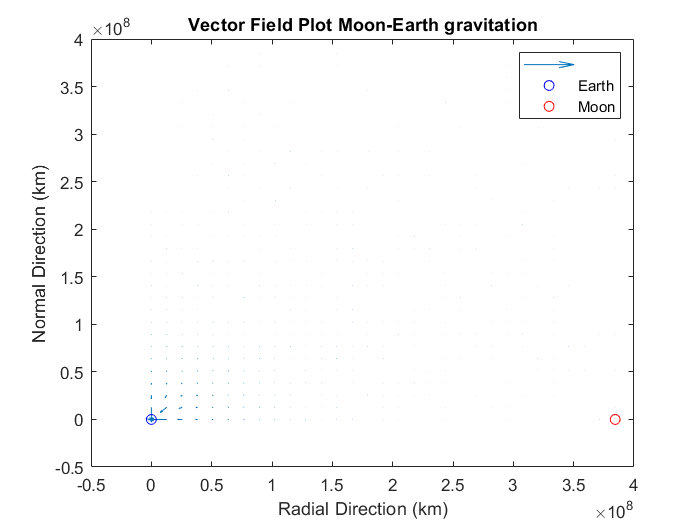



% gravitational force from Earth
R = (X.^2 + Y.^2).^0.5; % radial distance from Earth to each point
R(1,1) = Inf; % gravitational force undefined at center of earth
fx =  -mue * ms * X ./ R.^3; % total force in radial dir
fy = -mue * ms * Y ./ R.^3; % total force in normal dir


% gravitational force from Moon
R = ((X-emdist).^2 + Y.^2).^0.5; % radial distance from Moon to each point
fx = fx + mum*ms*(emdist-X)./R.^3;
fy = fy - mum*ms*Y./R.^3;


% taking log of data

fx(isinf(fx)) = 0;
fy(isinf(fy)) = 0;
quiver(X, Y, fx, fy);
hold on
title("Vector Field Plot Moon-Earth gravitation")
xlabel("Radial Direction (km)")
ylabel("Normal Direction (km)")
plot(0, 0, 'bo')
plot(emdist, 0, 'ro')
legend('', 'Earth', 'Moon')
% insert images into graph
hold off

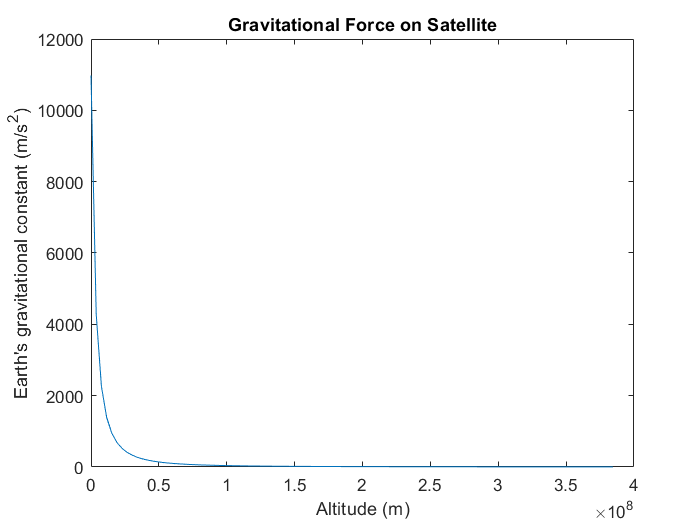

altref = emdist; % reference altitude in m
alt = 0:altref/100:altref;
plot(alt, mue*ms./(6378e3+alt).^2)
title("Gravitational Force on Satellite")
xlabel("Altitude (m)")
ylabel("Earth's gravitational constant (m/s^2)")